hierro = importHierroPlots("C:\Users\usuario\Desktop\Datos_Boya_Hierro\hierro.xlsx");

cyc = hierro(:, 1:3);
sb = hierro(:, 4:6);
rawOptode = hierro(:, 7:11);
co = hierro(: ,12:16);
phDef = hierro(:, 17:19);

% Eliminar filas vacías
nanCyc = isnan(cyc.Fluorescece);
cyc(nanCyc, :) = [];

nanSb = isnan(sb.SST);
sb(nanSb, :) = [];

nanOp = isnan(rawOptode.Oxy);
rawOptode(nanOp, :) = [];

nanCo = isnan(co.pCO2);
co(nanCo, :) = [];

nanPh = isnan(phDef.pHTis);
phDef(nanPh, :) = [];

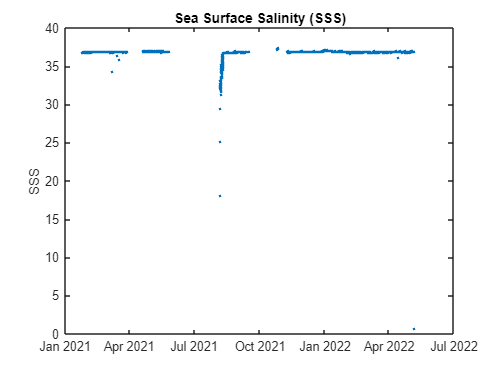

plot(sb.DateMicrocatSIP, sb.SSS, ".")
title("Sea Surface Salinity (SSS)")
ylabel("SSS")

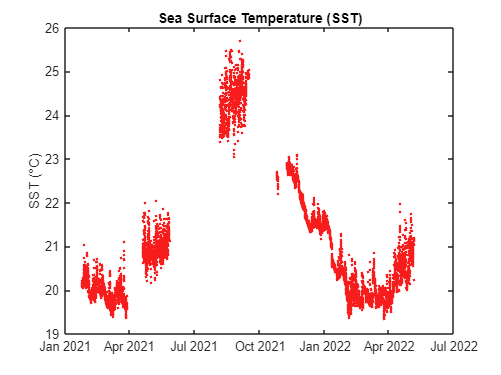

%ylim([35.5, 37.5])

plot(sb.DateMicrocatSIP, sb.SST, ".",  "Color", "#f71d1d")
ylabel("SST (°C)")
title("Sea Surface Temperature (SST)")

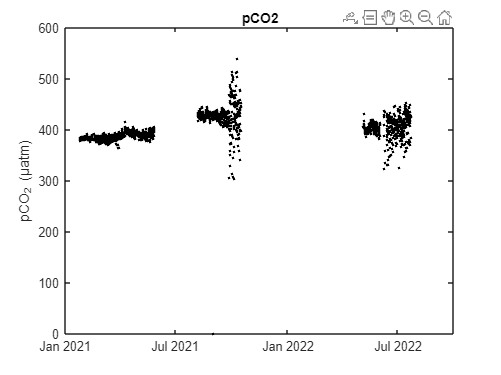

%ylim([16, 26])

plot(co.DateProOceanus, co.pCO2, "k.")
title("pCO2")
ylabel("pCO_{2} (µatm)")

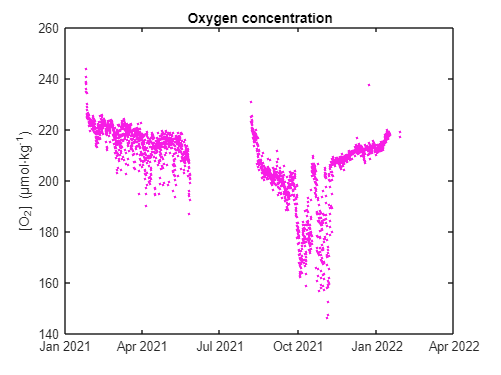

%ylim([300, 480])

plot(rawOptode.DateOptode, rawOptode.O2Concentration, ".", "Color", "#f71de5")
title("Oxygen concentration")
ylabel("[O_{2}] (µmol⋅kg^{-1})")

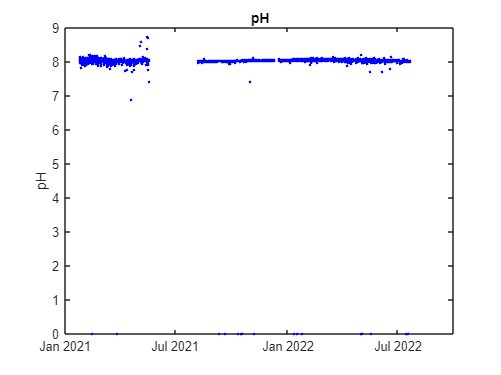


plot(phDef.DateSamipH, phDef.pHTis, ".", "Color", "blue")
title("pH")
ylabel("pH")

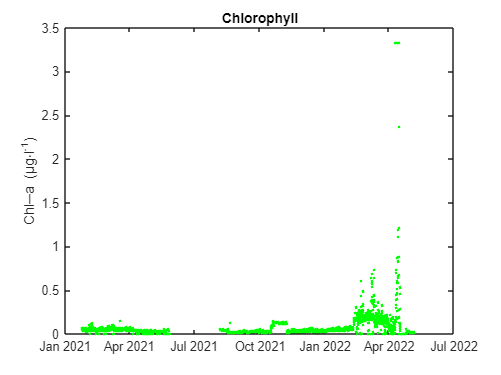

%ylim([7.9, 8.3])

plot(cyc.DateCyc, cyc.Chlorofila, "g.")
title("Chlorophyll")
ylabel("Chl─a (µg⋅l^{-1})")